# Pottery Presentation

## Ellipse Axis TF

clf;
figure
wn = 0.05;
z = 0.35;
tfr = tf([wn], [1 2*z*wn wn^2]);
step1 = linspace(0,400,600);
[r, t] = step(tfr, step1);
a_axis= r;
b_axis = 2*dcgain(tfr) - a_axis;
plot(t, a_axis)
hold on
b = 2*dcgain(tfr) - r

b =    40.0000
   39.9889
   39.9561
   39.9021
   39.8273
   39.7325
   39.6181
   39.4847
   39.3329
   39.1633


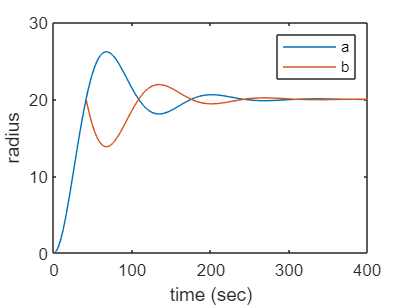

plot(t(63:end), b_axis(63:end))
legend("a", "b")
xlabel("time (sec)")
ylabel("radius")

## 2D top rim:

%% rim (THIS ONE WORKS*****) 

wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(40,1200,600);
[r, t] = step(tfr, step1);
%r = r*4;
a = r;
c = 2*dcgain(tfr) - r;
figure
hAx = axes('XLim',[-250 250], 'YLim',[-250 250], ...
    'Drawmode','fast', 'NextPlot','add');

axis(hAx, 'equal')

p = calculateEllipse(0, 0, a(1), c(1), step1(1));
hLine = line('XData',p(:,1), 'YData',p(:,2), 'EraseMode','xor',  ...
    'Color','r', 'LineWidth',3);


for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
    set(hLine,'XData',p(:,1), 'YData',p(:,2))  %# update X/Y data
%     pause(.10)                                 %# slow down animation
    drawnow                                    %# force refresh
    if ~ishandle(hLine), return; end           %# in case you close the figure
end


## Making it 3d

figure

wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(40,1200,600);
[r, t] = step(tfr, step1);

a = r;
c = 2*dcgain(tfr) - r;

p = calculateEllipse(0, 0, a(1), c(1), step1(1));
surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])

for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
    surf([p(:,1)'; p(:,1)'], [p(:,2)'; p(:,2)'], [10*ones(size(p(:,1)')); ones(size(p(:,1)'))])
    axis([-250 250 -250 250 0 11])
    drawnow                                    %# force refresh
    if ~ishandle(hLine), return; end           %# in case you close the figure
end

## Making it Pot shaped

figure
%% transfer function for major axis'
wn = 0.06;
z = 0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(0,400,600);
[r, t] = step(tfr, step1);
a = r;
c = 2*dcgain(tfr) - a;

%%calculate elipse coordinates
p = calculateEllipse(0, 0, a(1), c(1), step1(1));

%%make into a surf matrix

g= linspace(0, 2*pi, 36)';
h = repmat(g,1,36)';
xtrial = repmat(p(:,1), 1, 36);
ytrial = repmat(p(:,2), 1, 36);
for i = 1:length(g)
    xtrial2(:,i) = xtrial(:,i)*(sin(g(i)*0.7)+2);
    ytrial2(:,i) = ytrial(:,i)*(sin(g(i)*0.7)+2);
end 

surf(xtrial2, ytrial2,h)

%%animation: update for every t
for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
    xtrial = repmat(p(:,1), 1, 36);
    ytrial = repmat(p(:,2), 1, 36);
    for j = 1:length(g)
        xtrial2(:,j) = xtrial(:,j)*(sin(g(j)*0.9)+2);
        ytrial2(:,j) = ytrial(:,j)*(sin(g(j)*0.9)+2);
    end 
    surf(xtrial2, ytrial2,h)
    axis([-500 500 -500 500 0 6])
    drawnow                                    %# force refresh
    %if ~ishandle(hLine), return; end           %# in case you close the figure
end


## Unstable system

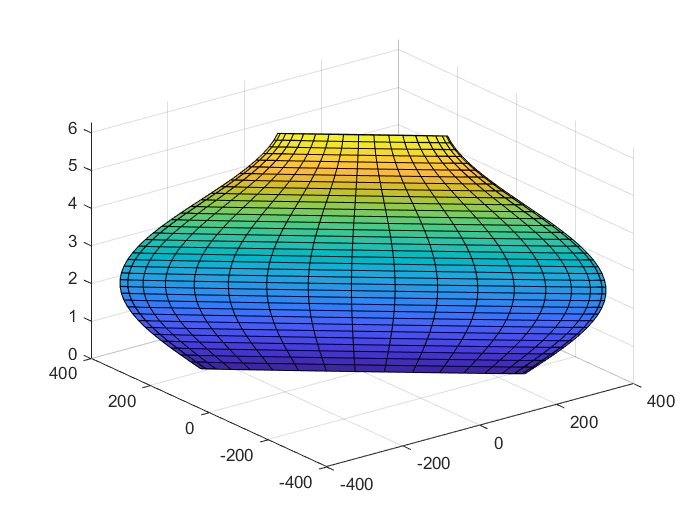

figure
%% transfer function for major axis'
wn = 0.06;
z = -0.1;
tfr = tf([5*wn], [1 2*z*wn wn^2]);
step1 = linspace(40,100,100);
[r, t] = step(tfr, step1);
a = r;
c = 2*dcgain(tfr) - a;

%%calculate elipse coordinates
p = calculateEllipse(0, 0, a(1), c(1), step1(1));

%%make into a surf matrix

g= linspace(0, 2*pi, 36)';
h = repmat(g,1,36)';
xtrial = repmat(p(:,1), 1, 36);
ytrial = repmat(p(:,2), 1, 36);
for i = 1:length(g)
    xtrial2(:,i) = xtrial(:,i)*(sin(g(i)*0.7)+2);
    ytrial2(:,i) = ytrial(:,i)*(sin(g(i)*0.7)+2);
end 

%% first plot
surf(xtrial2, ytrial2,h)

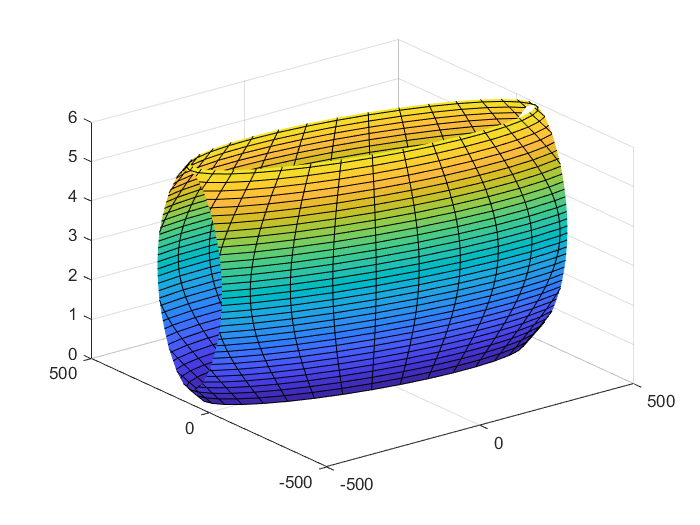


%%animation: update for every t
for i=1:numel(step1)
    p = calculateEllipse(0, 0, a(i), c(i), step1(i));
    xtrial = repmat(p(:,1), 1, 36);
    ytrial = repmat(p(:,2), 1, 36);
    for j = 1:length(g)
        xtrial2(:,j) = xtrial(:,j)*(sin(g(j)*0.5)+2);
        ytrial2(:,j) = ytrial(:,j)*(sin(g(j)*0.5)+2);
    end 
    surf(xtrial2, ytrial2,h)
    axis([-500 500 -500 500 0 6])
    drawnow                                    %# force refresh
    %if ~ishandle(hLine), return; end           %# in case you close the figure
end